# V768 - Measuring Vision with Psychophysics

## Lab 5 - Adaptive Methods

In this lab, ...

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Explain the motivations for the development of adaptive methods.

- Describe the differences between an experiment using an adaptive staircase method and an experiment using the method of constant stimuli.

### Questions

- Why do some experiments require pairs of staircases, when others do not?

- What are the main motivations for using staircases instead of the method of constant stimuli?

- Include and write a caption for the second figure in Part B. Step 3. (Visualize your data; this figure has the two staircases separated.)

- Why do we use the log-likelihood cost function instead of the mean squared error to fit the psychometric function when we collect data using a staircase method?

- Include and write a caption for the second figure in Part B. Step 5. (Fit your data)

- What was the point of subjective equality for your data?  Do you think your data was biased, why or why not?

- What was your discrimination threshold?  Explain what that means in terms of what orientations you can and cannot discriminate.

## The Staircase Method

The staircase method allows the experimenter to efficiently measure a perceptual threshold by adaptively adjusting the stimulus level based on the observer's recent performance.  This method often reduces the number of trials that an observer needs to perform.

#### How does this procedure work?

The most common staircase approach is the "two down, one up" staircase.  The way this works for a forced choice **detection task** (like the 2AFC contrast sensitivity experiment we did last week) is that if you are correct twice in a row the stimulus level decreases by one step and if you are wrong the stimulus level increases by one step.  Below you can see an example of how this might work over 60 trials for a detection task.

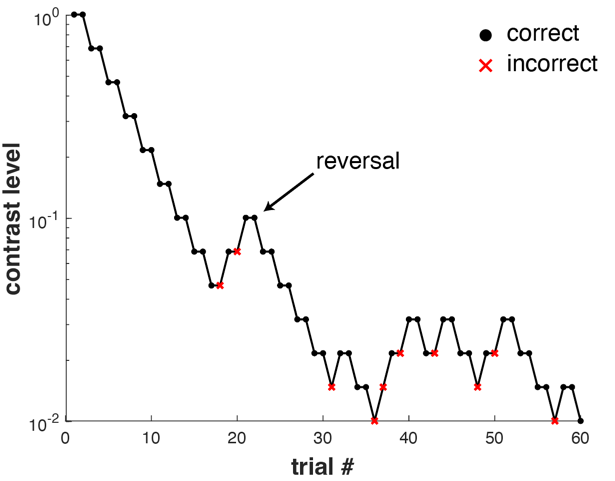

Staircases are often visualized in this way. And they actually look a little bit like staircase with steps that go up and down along some stimulus feature as the trials progress.  The **reversals **are points where there is a change in direction to the changes to the stimulus level.  While we won't use these reversals for our analyses, older papers often discuss and rely on these reversal points in their analyses. 

### Staircases for discrimination tasks.

Staircases actually work slightly differently in a **discrimination task** (like the orientation discrimination task we will complete today). For example, in a 2IFC orientation discrimination task, you would be asked to report whether the second interval was more clockwise or counterclockwise than the first interval. Here is an example trial, where the correct answer would be counter-clockwise:

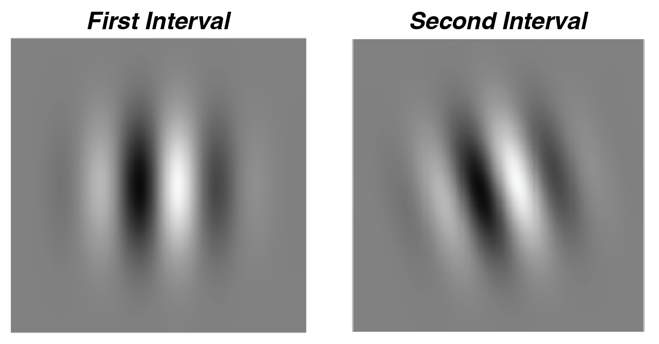

For this orientation discrimination experiment, the "one up, two down" staircase would be based on your choice of clockwise or counterclockwise. If you report that one trial is counterclockwise, the stimulus level increases by one step. If you report that two trials in a row clockwise, the stimulus level decreases by one step. Below we have plotted a staircase for an orientation discrimination task.  In this case the x-axis shows the trial number, and the y-axis shows the difference in the orientation between the two intervals (2nd interval orientation - 1st interval orientation).

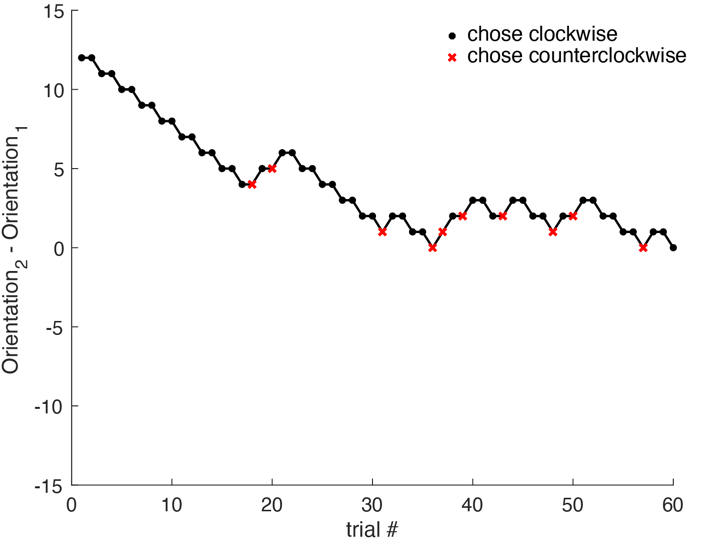

You might notice that this staircase is predominantly operating on trials where the 2nd interval orientation was clockwise of  the first interval.  This only captures half of the points you might want to measure in an orientation discrimination experiment.  

**What about the orientations that are counter-clockwise?**  Usually for discrimination experiments, the staircases are completed in pairs, one staircase that starts clockwise and one that starts counter-clockwise.  Their rules for adjusting the stimulus level across trials work in opposite ways:  

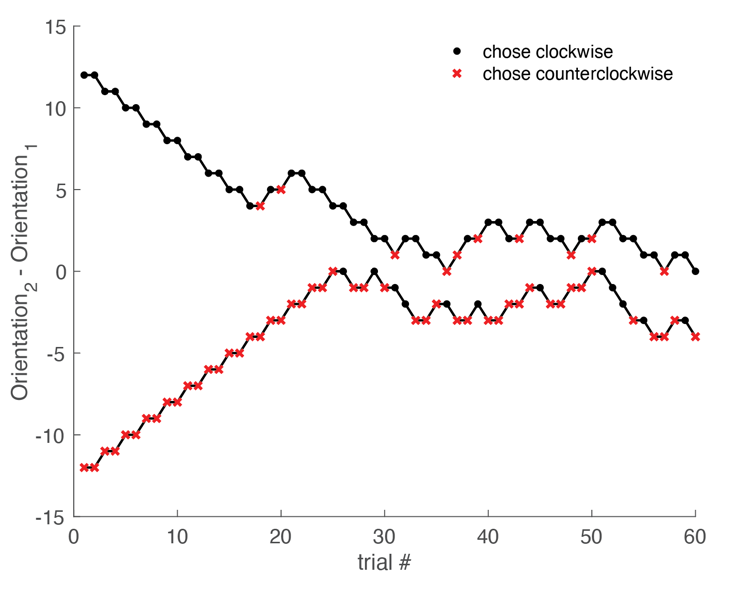

The staircase that starts clockwise (near the top) follows the rule that if you report that two trials in a row clockwise (black dots), the stimulus level decreases by one step and if you report one trial counter clockwise (red x), the stimulus level increases by one step.  The staircase that starts counter-clockwise (near the bottom) follows the rule that if you report that two trials in a row counter-clockwise (red x), the stimulus level increases by one step,  and if you report one trial clockwise (black dot), the stimulus level decreases by one step.

## Part A.  Simulating an orientation discrimination experiment

Let's build our intuitions about these staircases in a discrimination experiment, by simulating an orientation discrimination experiment.  

### Step 1. Choose parameters for your simulation.

You can use a psychometric curve to simulate performance on this task.  The first step is to choose a set of parameters for the psychometric curve.

% define psychometric function
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

mu = 0;
sigma = 3;
guess_rate = 0;
lapse_rate = 0;
params = [mu,sigma,guess_rate,lapse_rate];

### Step 2. Visualize the psychometric curve.

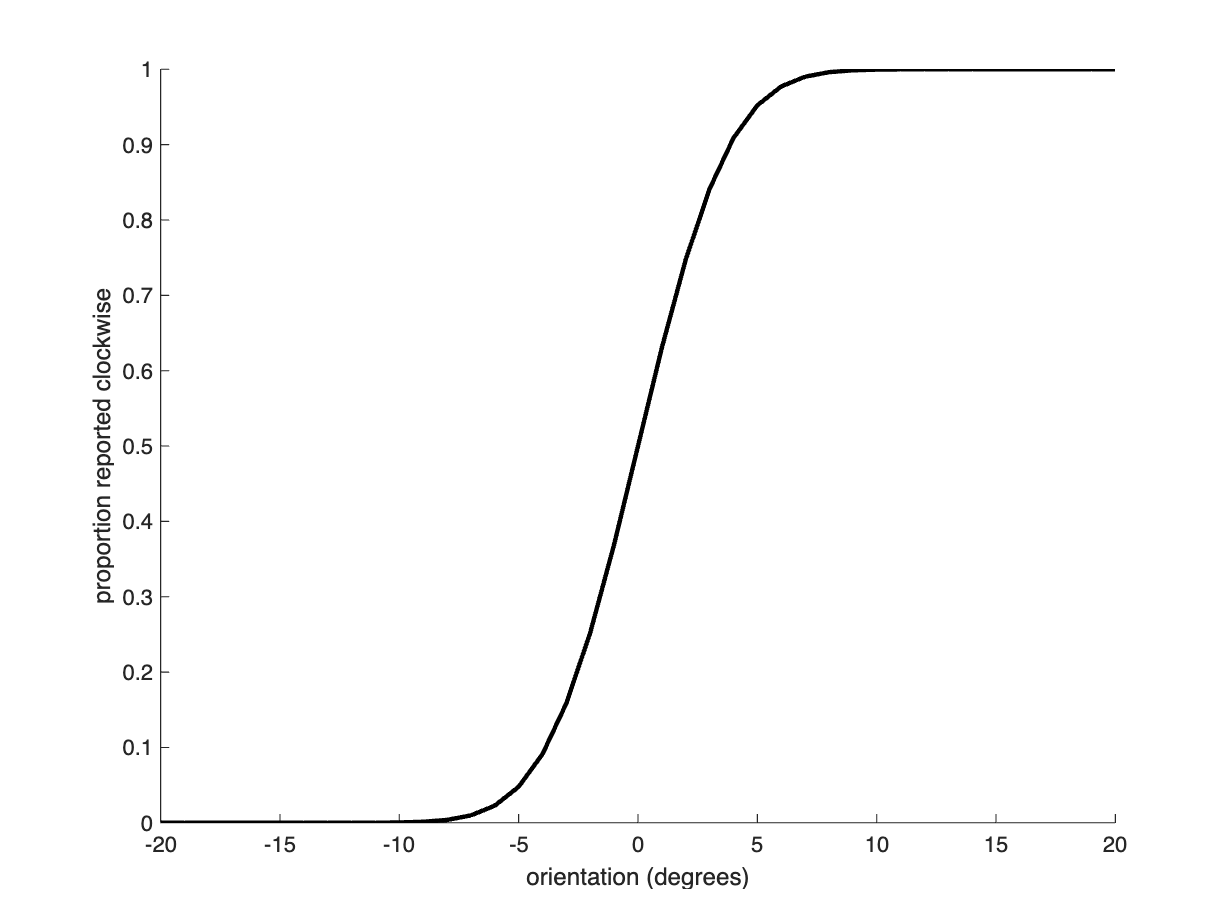

orientation_axis = -20:20;
prob_axis = psyfxn(params,orientation_axis);
figure();
plot(orientation_axis,prob_axis,'k','LineWidth',2);
xlabel('orientation (degrees)'); ylabel('proportion reported clockwise');
box off;

drawnow;

### Step 3. Simulate trials using the staircase method.

Now we will simulate trials using a one-up, two-down staircase.  For the staircase simulation, we will simulate one trial at a time.  This is because the orientation presented on a trial is dependent on the previous orientations presented and performance.  

nTrialsPerStaircase=60;
initial_orientation = 12;
staircase_step = 1; % degrees

% set up vectors for staircase.
orientation_levels_staircase = nan(nTrialsPerStaircase,1);
orientation_levels_staircase(1) = initial_orientation;
trials_staircase = nan(nTrialsPerStaircase,1);

counter = 0;
for ii=1:nTrialsPerStaircase

    % simulate current trial
    p=psyfxn(params,orientation_levels_staircase(ii));
    trials_staircase(ii) = binornd(1,p);

    % generate next trial
    if ii < nTrialsPerStaircase    
        if trials_staircase(ii) ==1 % chose clockwise
            counter = counter+1;
            if counter == 2
                orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii)-staircase_step;
                counter = 0; % reset
            else                    
                orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii);
            end
        else  % chose counter-clockwise
            orientation_levels_staircase(ii+1) = orientation_levels_staircase(ii)+staircase_step;
            counter = 0; % reset
        end

    end

end

### Step 4. Visualize simulated staircase.

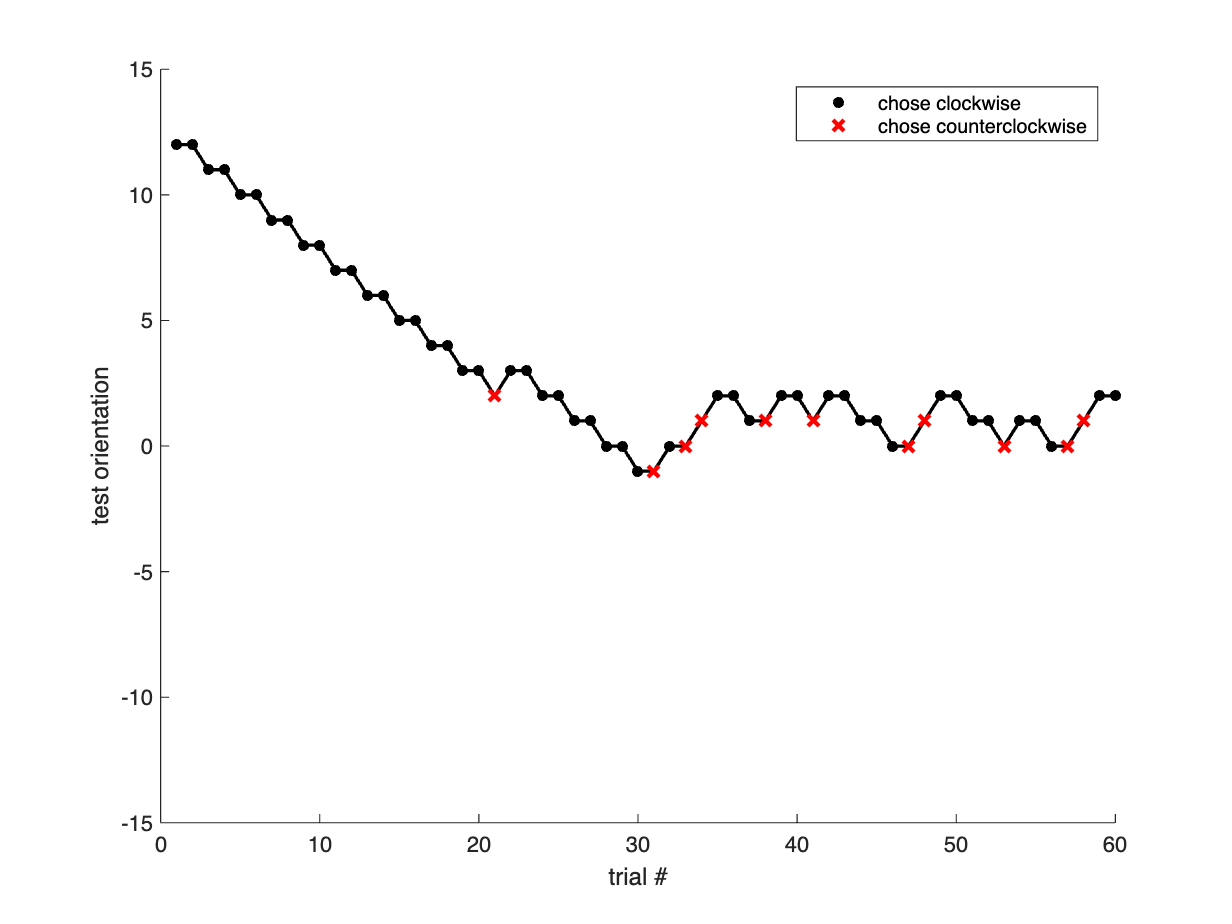

trialNo = 1:nTrialsPerStaircase;
figure();
plot(trialNo,orientation_levels_staircase,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase==1),orientation_levels_staircase(trials_staircase==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase==0),orientation_levels_staircase(trials_staircase==0),'rx','MarkerSize',7,'LineWidth',2)

box off;
xlabel('trial #'); ylabel('test orientation');
ylim([-15,15])
legend('','chose clockwise','chose counterclockwise');

drawnow;

### Step 5.  Simulate the second staircase

Recall that staircases for discrimination tasks are usually performed in pairs. Notice in the figure above that the staircase does not often go below 0 degrees.  This second staircase will provide data for the lower part of the graph.

% set up vectors for staircase.
initial_orientation = -12;
orientation_levels_staircase_2 = nan(nTrialsPerStaircase,1);
orientation_levels_staircase_2(1) = initial_orientation;
trials_staircase_2 = nan(nTrialsPerStaircase,1);

counter = 0;
for ii=1:nTrialsPerStaircase

    % simulate current trial
    p=psyfxn(params,orientation_levels_staircase_2(ii));
    trials_staircase_2(ii) = binornd(1,p);

    % generate next trial
    if ii < nTrialsPerStaircase    
        if trials_staircase_2(ii) == 0 % chose counter-clockwise
            counter = counter+1;
            if counter == 2
                orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii)+staircase_step;
                counter = 0; % reset
            else                    
                orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii);
            end
        else  % chose counter-clockwise
            orientation_levels_staircase_2(ii+1) = orientation_levels_staircase_2(ii)-staircase_step;
            counter = 0; % reset
        end

    end

end


And now we can visualize both staircases.

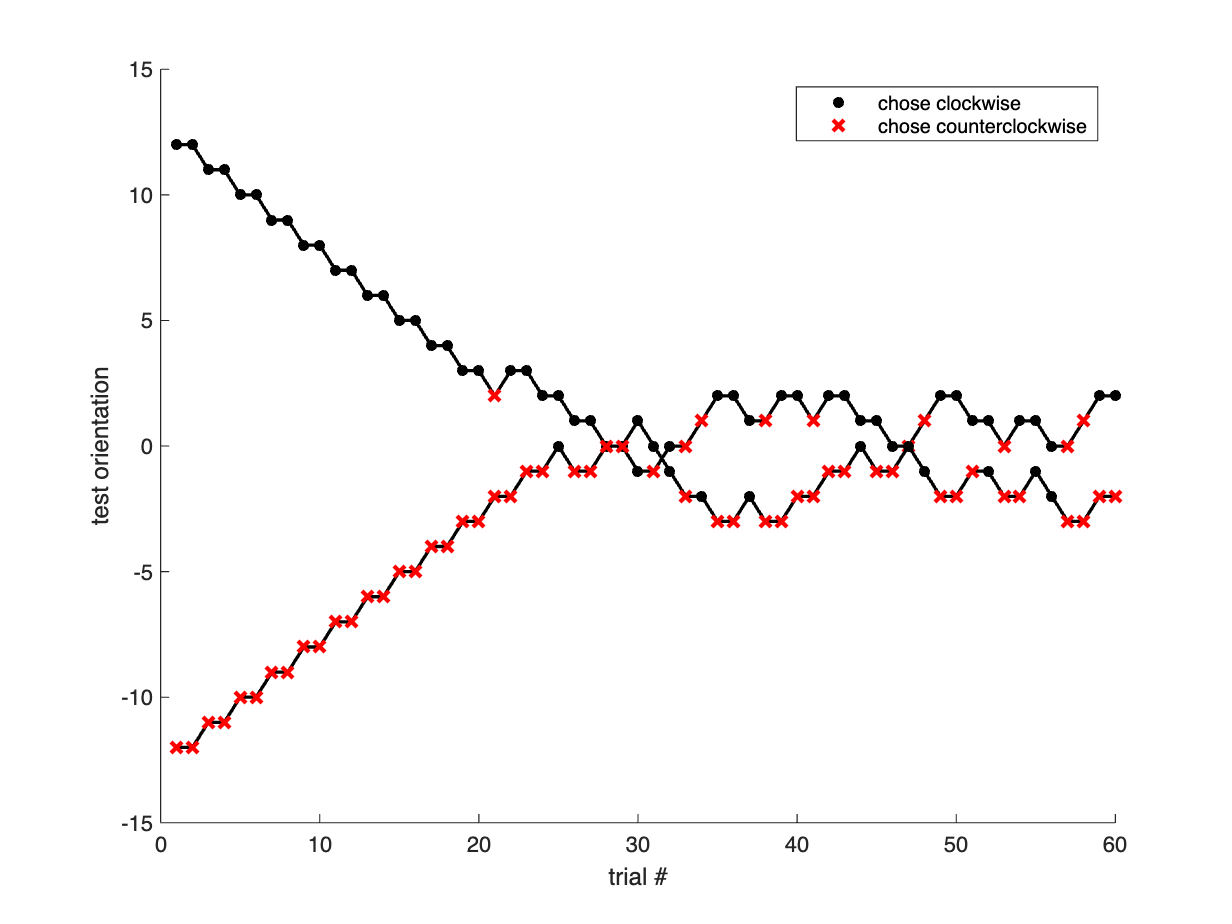

trialNo = 1:nTrialsPerStaircase;
figure();
plot(trialNo,orientation_levels_staircase,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase==1),orientation_levels_staircase(trials_staircase==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase==0),orientation_levels_staircase(trials_staircase==0),'rx','MarkerSize',7,'LineWidth',2)
plot(trialNo,orientation_levels_staircase_2,'k','LineWidth',1.5); hold on;
plot(trialNo(trials_staircase_2==1),orientation_levels_staircase_2(trials_staircase_2==1),'k.','MarkerSize',15)
plot(trialNo(trials_staircase_2==0),orientation_levels_staircase_2(trials_staircase_2==0),'rx','MarkerSize',7,'LineWidth',2)

box off;
xlabel('trial #'); ylabel('test orientation');
ylim([-15,15])
legend('','chose clockwise','chose counterclockwise');

drawnow;

### Step 6. Analyze the results of the simulation.

Even though we have collected this data in a somewhat different way than the method of constant stimuli, we can still use the psychometric function approach to analyze the data.  

**Note**:  Historical papers using staircases will sometimes compute the average stimulus values from the "last n reversals" to measure threshold. This was a common approach to evaluating staircases in the past but it is no longer common practice and should be avoided.

simulated = array2table([[orientation_levels_staircase;orientation_levels_staircase_2],[trials_staircase; trials_staircase_2]],...
    "VariableNames",{'orientation_level','response'});
simulation_results = grpstats(simulated,"orientation_level");
simulation_results = renamevars(simulation_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prop_clockwise"]);
simulation_results.Properties.RowNames = {};
disp(simulation_results)

    orientation_level    n_trials    prop_clockwise
    _________________    ________    ______________

           -12               2                0    
           -11               2                0    
           -10               2                0    
            -9               2                0    
            -8               2                0    
            -7               2                0    
            -6               2                0    
            -5               2                0    
            -4               2                0    
            -3               8                0    
            -2              14          0.21429    
            -1              15          0.33333    
             0              15              0.6    
             1              15          0.66667    
             2              13          0.92308    
             

### **Step 7. Fit the psychometric curve**

In the last few labs we have used lsqcurvefit to fit our data.  We can't do that anymore because that kind of fitting relied on the assumption that each probability value should be weighted the same.  With the staircase method we can no longer weight each point the same because we don't have the same number of trials per orientation level.

Intead of lsqcurvefit, we're going to use a function called fmincon.  You're probably thinking to yourself, how do I pronounce that?  it is pronounced f - min - con.  It is short for: **f**inding the **min**imum of a **c**onstrained multivariable function.  You can read a little bit more about it below:

help fmincon

 fmincon finds a constrained minimum of a function of several variables.
    fmincon attempts to solve problems of the form:
     min F(X)  subject to:  A*X  <= B, Aeq*X  = Beq (linear constraints)
      X                     C(X) <= 0, Ceq(X) = 0   (nonlinear constraints)
                               LB <= X <= UB        (bounds)
     
    fmincon implements four different algorithms: interior point, SQP,
    active set, and trust region reflective. Choose one via the option
    Algorithm: for instance, to choose SQP, set OPTIONS =
    optimoptions('fmincon','Algorithm','sqp'), and then pass OPTIONS to
    fmincon.
                                                            
    X = fmincon(FUN,X0,A,B) starts at X0 and finds a minimum X to the 
    function FUN, subject to the linear inequalities A*X <= B. FUN accepts 
    input X and returns a scalar function value F evaluated at X. X0 may be
    a

In order to use it we have to define a cost function to minimize.  When you used the lsqcurvefit, your cost function was mean squared error.  With fmincon, we're going to use a **negative log-likelihood** cost function.  

**What is a likelihood? **You can think about it in terms of the psychometric curve and the data that we have collected from our observers. We want to find the psychometric curve, $\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right),$ that is the most likely model of our data.  We need to find the values of $\mu ,\sigma ,\gamma ,\mathrm{and}\;\lambda$ that provide the best explanation for our data.  

For example, let's say that for the orientation level of 0 degrees, your participant collected 10 trials, choosing clockwise for 5 of the trials and choosing counter-clockwise for 5 of the trials.  If the psychometric function at 0 degrees returns a probability of $\approx$.5, this is a good match to your data, so the likelihood should be high.  If you have a psychometric function that returns a probability of .2, that would be a bad match, and the likelihood should be low. The likelihood is just a formal way of answering the question "how likely is it that this psychometric function with these specific values for $\mu ,\sigma ,\gamma ,\lambda$ generated my data?"

**Why log-likelihood?**  It turns out that likelihood values are often tiny decimals (e.g., 0.00001) which can become difficult for the computer to deal with, so we take the logarithm to make them easier to work with. 

**Why negative log-likelihood?** When we optimize a model (e.g., fitting a psychometric curve), we want to maximize the likelihood of the observed data.  However, since MATLAB and many other optimization algorithms are built for minimization, we flip the sign and use negative log-likelihood as a cost function. The optimization finds parameters that minimize negative log-likelihood, which is equivalent to maximizing the likelihood.

**What negative log-likelihood cost function should I use? **Because the psychometric curve expresses probabilities for discrete events (trials), the right likelihood function to use is the binomial probability function:


$${N}\choose{k}$$

$$p^k \cdot (1-p)^{N-k}$$


where $p$ is the probability returned by the psychometric function for a particular orientation level, given the current parameters; $k$ is the number of trials reported clockwise; and $N$ is the total number of trials, meaning that$N-k$ is the number of trials reported counter-clockwise.  

This first component ${N}\choose{k}$ is a constant.  It is there to make sure that the probability function sums to 1.  In the context of optimization we can ignore it.  That leaves us with: $p^k \cdot (1-p)^{N-k}$.  Apply the log and we end up with following log-likelihood function:


$$k\cdot log(p)$$

$$+ (N-k)\cdot log(1-p)$$


Now we're going to use this expression to calculate the log-likelihood of the psychometric function at each orientation level, sum over all those log-likelihoods and multiple by -1 to get the negative log-likelihood.

**And how is that going to help me fit my data?**

Remember that this negative log-likelihood is going to be used a cost function for an optimization.  The optimization process will change the parameters of the psychometric curve to minimize the value of the negative log-likelihood.  It will find the parameters of the psychometric curve that are best explanation, or the most likely, for your data.

function negLL = negLogLikelihood(params, x, k, N)
    % calculate the probability from the psychometric function
    p = (normcdf(x, params(1), params(2)) * (1 - params(3) - params(4))) + params(3);
    p = min(max(p, 1e-5), 1-1e-5);  % Avoid log(0)    
    % Compute negative log-likelihood
    negLL = -sum(k .* log(p) + (N - k) .* log(1 - p));
end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


initParams = [1,5,.1,.1];

[bestParams, negLL] = fmincon(@(params) ...

                 fit        true
              __________    ____

    mu          -0.24103     0  
    sigma         1.7377     3  
    gamma     1.8437e-07     0  
    lambda    1.8473e-07     0  



    negLogLikelihood(params,...
    simulation_results.orientation_level,...
    simulation_results.prop_clockwise.*simulation_results.n_trials,...
    simulation_results.n_trials), initParams,...
    [],[],[],[],[-12,0,0,0],[12,100,.5,.5]);

The table below shows the best fit parameters alongside the true parameters.

simulation_fits = array2table([bestParams;params]','RowNames',{'mu','sigma','gamma','lambda'},'VariableNames',{'fit','true'});
disp(simulation_fits)

**Plot psychometric curve -- plot the data and the fitted curve.**

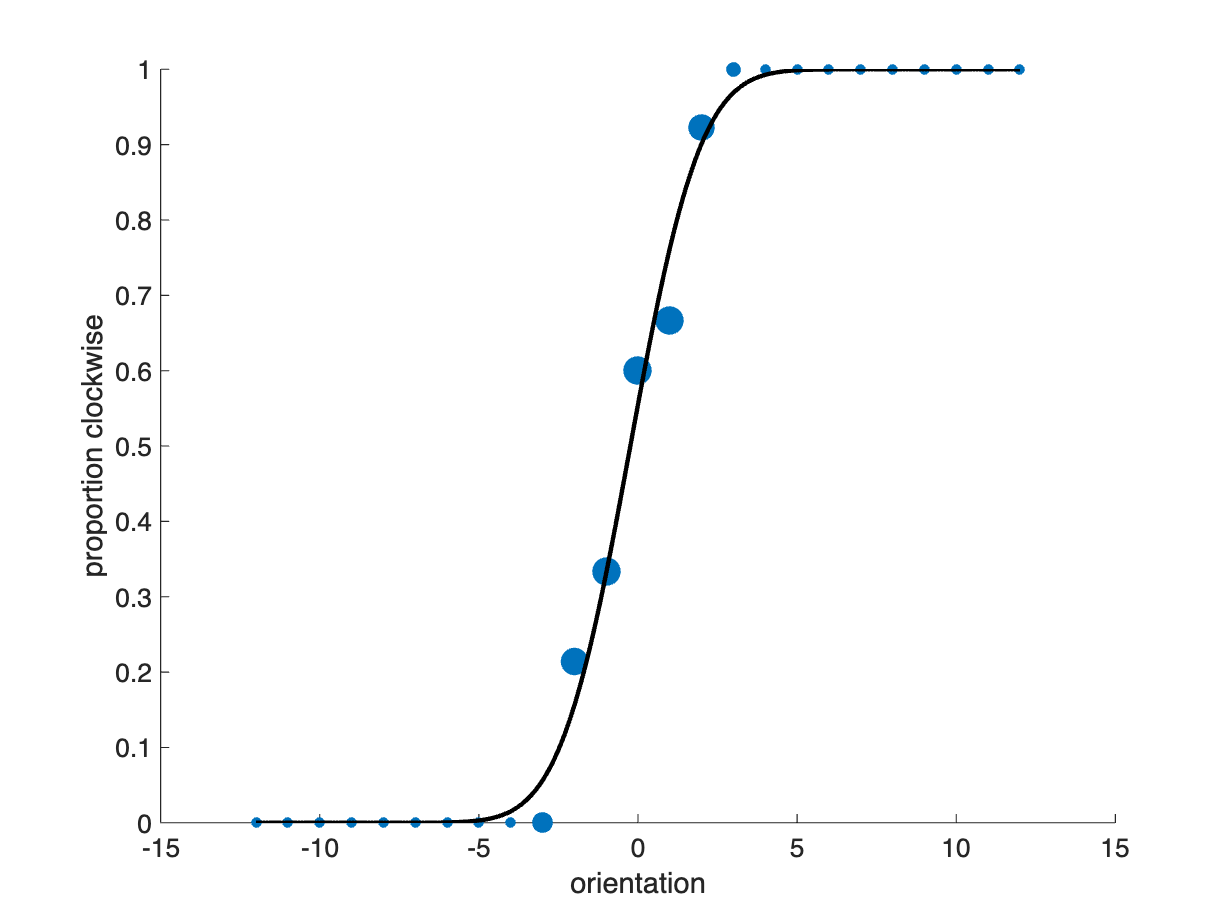

xx = -12:.1:12;
yy = psyfxn(bestParams,xx);


figure(); hold on;
scatter(simulation_results.orientation_level,...
    simulation_results.prop_clockwise,...
    100*simulation_results.n_trials,...
    '.')
plot(xx,yy,'k','LineWidth',2)
set(gca,'FontSize',12);
xlabel('orientation'); ylabel('proportion clockwise');
drawnow;

Wow... That was a lot of work.  **Why should we use staircases if it makes evaluating performance a little trickier?**

Notice that we set our two staircases to run 60 trials each, for a total of 120 trials. For a comparable simulation using method of constant stimuli, I would probably choose present the stimulus at at least 9 orientation levels, and I would require at least 30 trials per point.  At minimum, that would require that I perform 270 trials, which is more than twice the staircase simulation.  In an actual experiment, that means it would take less than half the time to do the experiment!

**How is it possible to use fewer trials with a staircase?** We need more data where the psychometric function is changing (in the middle).  The region where this occurs might be slightly different from across observers, so the staircase approach allows performance to dictate where we collect more data.  We don't have to collect as much data because we don't collect as much data where performance is very obvious.

## Part B. Simulating orientation discrimination 

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "adaptive-methods", and run that experiment.  The experiment is a 2IFC orientation discrimination experiment.  Your job on each trial will be to indicate whether the second interval gabor was tilted clockwise or counter-clockwise relative to the first interval gabor. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 132 trials.  

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("adaptive-methods", "data");
if ~exist(data_dir, 'dir')
    error("PsychoPy data folder not found. Try changing your " + ...
        "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id+ "*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_05-adaptive-methods_2025-02-09_19h50.12.686.csv


#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
expt_data(:,remove) = [];

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 132


### Step 3. Visualize your data

For this experiment, the stimulus was a grating. The grating orientation varied across stimulus presentations.

For each trial, PsychoPy saved the stimulus orientation and the response direction.  The stimulus orientation was reported in degrees relative to vertical (e.g., 5 degrees represents 5 degrees clockwise from vertical, -10 degrees represents 10 degrees counter-clockwise from vertical. The responses were stored as string values with clockwise as 'cw' and counter-clockwise 'ccw'.

% stash the stimulus orientation and response
stimulus_orientation = expt_data.staircase_intensity;
response_dir = expt_data.response;

% convert the response key to 1 for clockwise and -1 for counterclockwise
% (to match stimulus location)
response = double(strcmp(response_dir,'cw'));

#### Determine whether responses were correct or incorrect

There are two ways for the responses to be correct: (1) if the stimulus was present clockwise and the person reported it clockwise, (2) if the stimulus was presented counter-clockwise and the person reported it counter-clockwise

% determine whether responses were correct or incorrect
resp_correct = (stimulus_orientation)>0 == response;

% display overall performance
fprintf('overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

overall percentage correct = 75.76%


#### Visualize the two interleaved staircases.

During the experiment you were performing ***interleaved*** trials from two staircases, as well as a handful of "easy trials".  What we mean by interleaved is that we switched between two staircases during the experimental block, sometimes performing a trial from the first staircase and sometimes from the second staircase.  Interleaving staircases is usually a good idea as it prevents participants from being able to track the progress of the staircase and use that information to help inform their decisions.

Let's visualize the trials in this experiment by plotting the orientation of the second grating on each trial:

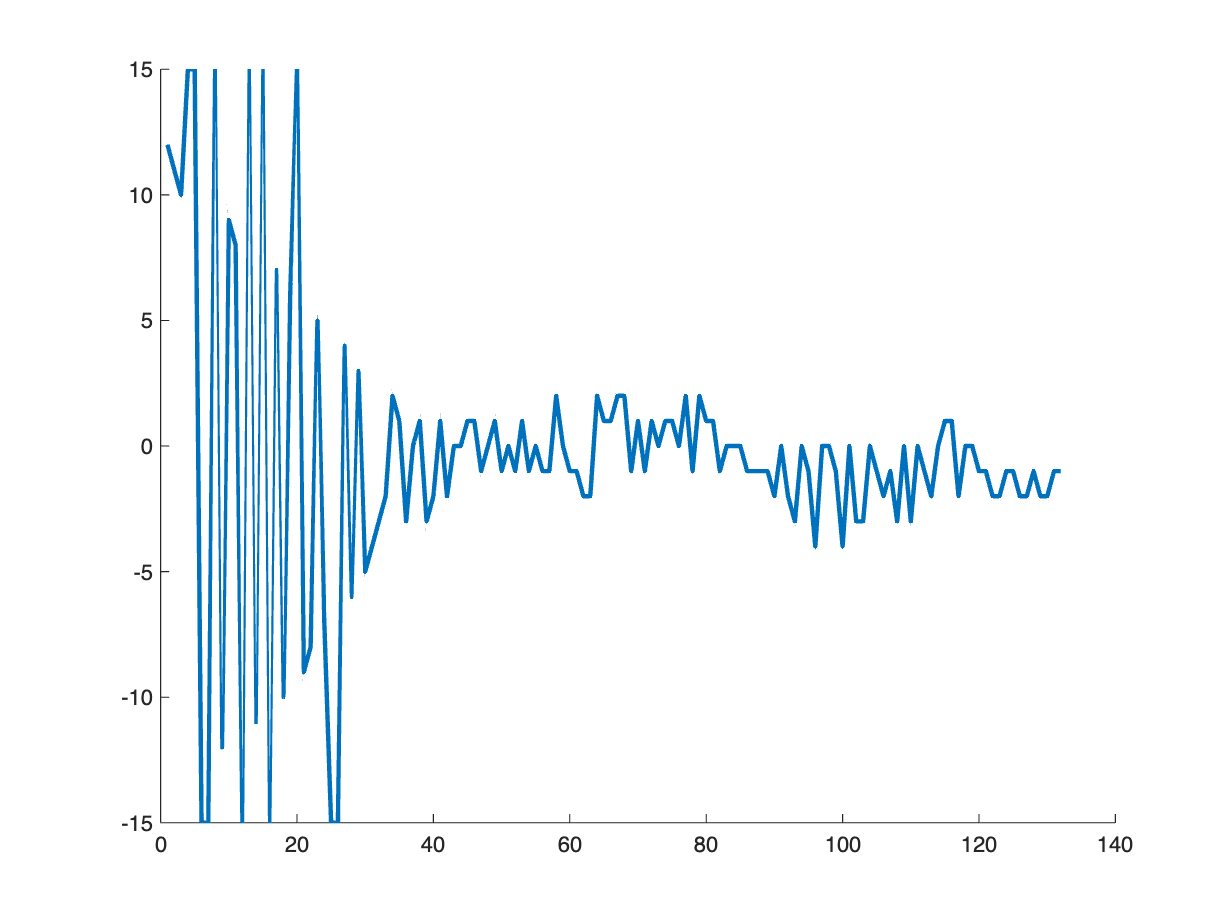

figure(); 
plot(stimulus_orientation,'LineWidth',2)
box off;

drawnow;

To make these staircases look more like the visualization of our simulations, we have to plot the two staircases and the easy trials separately.

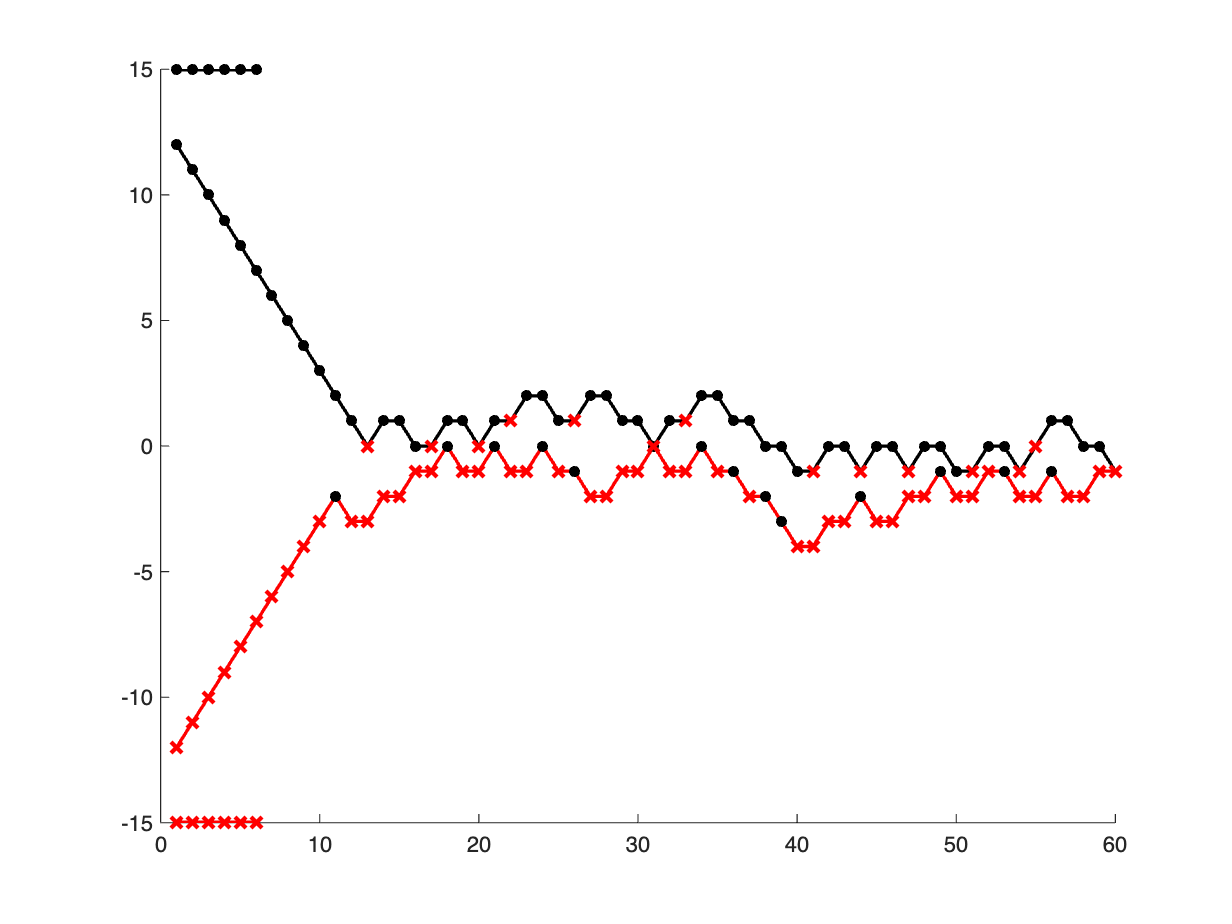

whichStaircase = expt_data.staircase_label;

idx_cw = strcmp(whichStaircase,'cw');
idx_ccw = strcmp(whichStaircase,'ccw');
idx_hi = strcmp(whichStaircase,'hi');
idx_lo = strcmp(whichStaircase,'lo');

idx_resp = expt_data.staircase_response==1;

figure(); hold on;
plot(stimulus_orientation(idx_cw),'k','LineWidth',1.5)
plot(stimulus_orientation(idx_ccw),'r','LineWidth',1.5)
plot(stimulus_orientation(idx_hi),'k','LineWidth',2)
plot(stimulus_orientation(idx_lo),'r','LineWidth',2)

plot(expt_data.staircase_thisRepN(idx_resp),stimulus_orientation(idx_resp),'k.','MarkerSize',15)
plot(expt_data.staircase_thisRepN(~idx_resp),stimulus_orientation(~idx_resp),'rx','MarkerSize',7,'LineWidth',2)

drawnow;

Now you can see the two interleaved staircases and the handful of easy trials at -15 and +15 degrees.

**Why perform easy trials? **The staircases won't spend much time on the floor and the ceiling of the psychometric curve.  These easy trials will make it easier for us to properly fit the guess rate ($\gamma$) and the lapse rate ($\lambda$).

### Step 4. Analyze your data.

#### Determine percentage correct per condition.

% average across responses per contrast level
analysis_table = table(response, expt_data.staircase_intensity, ...
    'VariableNames',["response", "orientation"]);
expt_results = grpstats(analysis_table, ["orientation"]);
expt_results = renamevars(expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prop_clockwise"]);
expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
orientation_levels = unique(expt_results.orientation);
n_orientation = length(orientation_levels);

% display results   `
disp(expt_results)

    orientation    n_trials    prop_clockwise
    ___________    ________    ______________

        -15            6                0    
        -12            1                0    
        -11            1                0    
        -10            1                0    
         -9            1                0    
         -8            1                0    
         -7            1                0    
         -6            1                0    
         -5            1                0    
         -4            3                0    
         -3            8            0.125    
         -2           16           0.1875    
         -1           28             0.25    
          0           23          0.78261    
          1           17          0.82353    
          2            7                1    
          3            1                1    
          4            

### Step 5. Fit your data.

#### Fit and plot performance in the form of a psychometric curve.

initParams = [1,5,.1,.1];

[bestExptParams, negLL] = fmincon(@(params) ...
    negLogLikelihood(params,...
    expt_results.orientation,...
    expt_results.prop_clockwise.*expt_results.n_trials,...
    expt_results.n_trials), initParams,...
    [],[],[],[],[-12,0,0,0],[12,100,.5,.5]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


The table below shows the best fit parameters alongside the true parameters.

expt_fits = array2table([bestExptParams]','RowNames',{'mu','sigma','gamma','lambda'},'VariableNames',{'fit'});
disp(expt_fits)

                 fit    
              __________

    mu          -0.58016
    sigma         1.4148
    gamma     9.9941e-06
    lambda    5.1307e-08



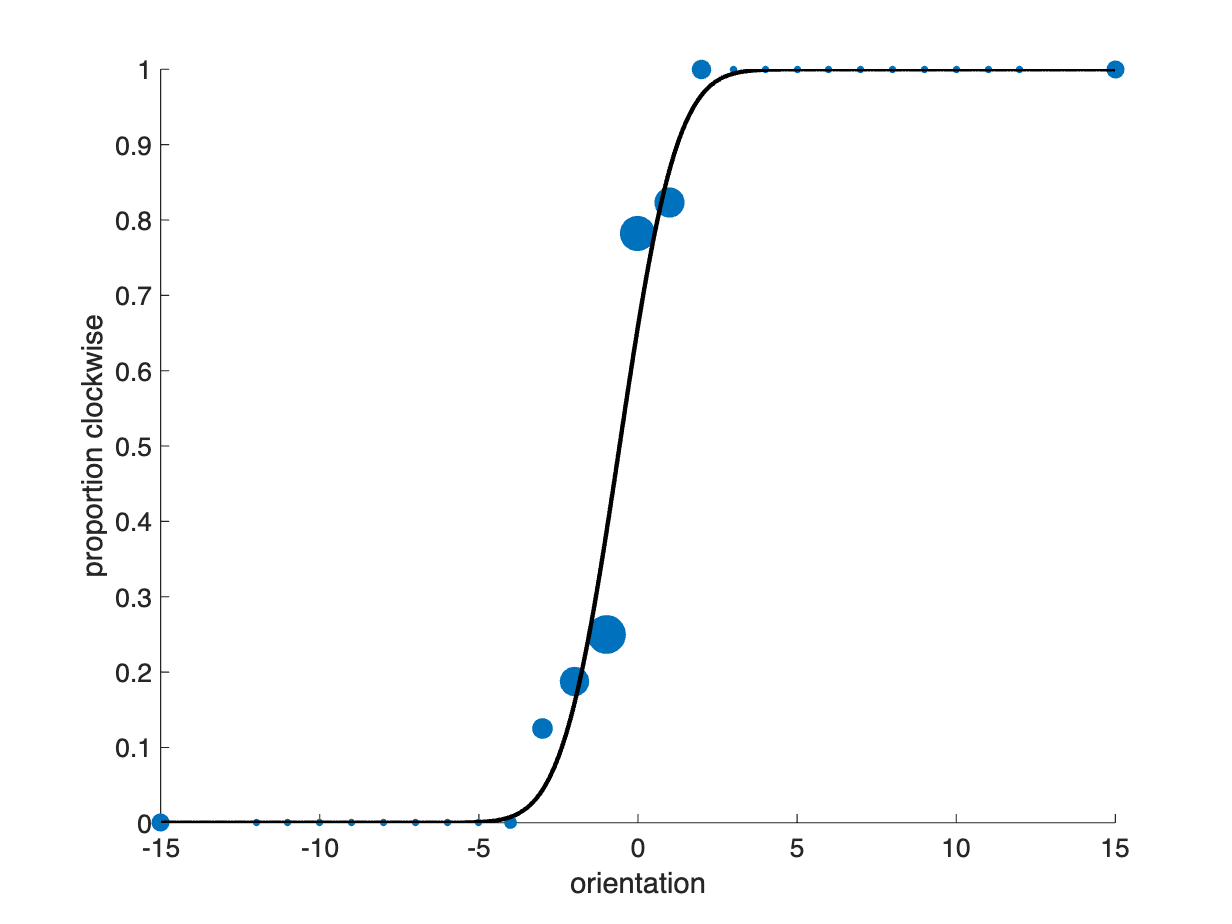

figure();
xx = -15:.1:15;
yy = psyfxn(bestExptParams,xx);

figure(); hold on;
scatter(expt_results.orientation,...
    expt_results.prop_clockwise,...
    100*expt_results.n_trials,...
    '.')
plot(xx,yy,'k','LineWidth',2)
set(gca,'FontSize',12);
xlabel('orientation'); ylabel('proportion clockwise');

drawnow

### Step 6. Make inferences from your data.

**What do you see?** 

There are a few important points we can measure on this curve, using the inverse psychometric function:

(1) the point of subjective equality (PSE), which for this experiment will tell us whether this participant has a bias in their response (chooses more clockwise vs. counterclockwise), and 

(2) the discrimination threshold, which we can calculate by finding the orientation level at p=.75 and p=.25

**What do you think?** Is your data biased?  What is your discrimination threshold and what does that mean?

% define inverse psychometric function
ipsyfxn = @(c,p) norminv((p - c(3))/(1 - c(3) - c(4)), c(1), c(2));
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

bias = ipsyfxn(bestExptParams,.5)

bias = -0.5802


discrimination_threshold = (ipsyfxn(bestExptParams,.75) - ipsyfxn(bestExptParams,.25))/2

discrimination_threshold = 0.9543